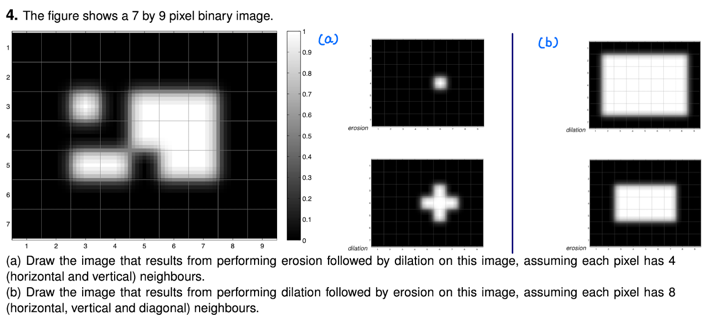

im = [zeros(2,9)
    0 0 1 0 1 1 1 0 0
    0 0 0 0 1 1 1 0 0
    0 0 1 1 0 1 1 0 0
    zeros(2,9)]

im =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     1     1     0     0
     0     0     0     0     1     1     1     0     0
     0     0     1     1     0     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 4 neighbours
SE_4 = strel("diamond", 1);
erosion_4 = imerode(im, SE_4)

erosion_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


dailation_4 = imdilate(erosion_4, SE_4)

dailation_4 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     1     1     1     0     0
     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



% 8 neighbours
SE_8 = strel("square",3);
dailation_8 = imdilate(im, SE_8)

dailation_8 =      0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     1     1     1     1     1     1     1     0
     0     0     0     0     0     0     0     0     0


erosion_8 = imerode(dailation_8, SE_8)

erosion_8 =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0